Welcome to the workflow for analyzing and visualizing behavioral and neural data. Follow each of the following steps sequentially to begin.

*For Quick Code & Less Documentation go to: Reagan General Code > template_scripts > BehaviorTrackingScript_Step1*

Dependencies:

- APT                                      [https://github.com/kristinbranson/APT](https://github.com/kristinbranson/APT)

- JAABAST                             Wasabi > ReaganBullins >DependenciedAndToolboxes > JAABAST

- Reagan Code General         [https://github.com/rcbullins/General](https://github.com/rcbullins/General) 

Always run the following piece of code:

BASEPATH = 'C:\Users\bullinsr\OneDrive - University of North Carolina at Chapel Hill\Hantman_Lab\';
CODE_GENERAL = [BASEPATH 'Code\General\'];
JAABAST = [BASEPATH 'Code\Packages\JAABAST'];

SUB = 'jcr70';
EXPER_SESSION = '20191016';
APT = 'C:\MATLAB\APT-develop\APT-develop';
MOVIES = [BASEPATH 'ThalamusSP_Project\Data\jcr70\video\20191016\'];

addpath(genpath(CODE_GENERAL));

## **(Step 1) Animal Part Tracking (APT)**

Code Package & Installation Instructions: [https://github.com/kristinbranson/APT](https://github.com/kristinbranson/APT)

APT is a software that uses machine learning to track animal behavior. Commonly, we will track 4 points in the animal videos: Digit 2, Digit 4, Wrist, and Food Pellet. Open APT with the following code.

NOTE: APT cannot be placed on your onedrive. The spaces in "OneDrive - Uni..." will mess up the code. Place it locally.

addpath(APT);
lObj = StartAPT;

**Load the project**

The APT GUI will open. Go to File > Load Project. Then select a previously made tracker (built by yourself or someone else in lab) to build off of. Note: You will need the videos the tracker is built on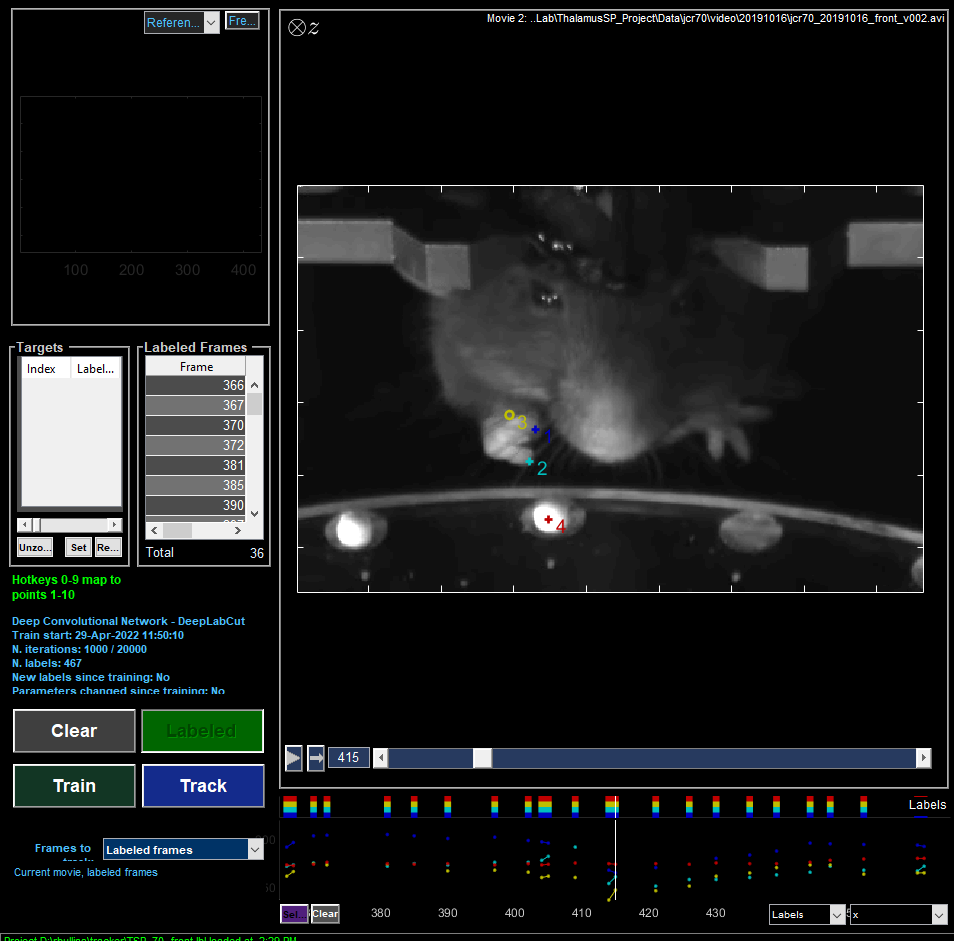  

An already made tracker along with all of the videos used to make the tracker can be found in Wasabi > ReaganBullins > APT_Tracker. Files: rcb_tracker_front.lbl & rcb_tracker_side.lbl. These tracking files were originally built off of Jeremy's tracker. *For Reagan this is located in One Drive >Hantman_Lab > APT_Tracker. *NOTE: You may have to alter the paths of the videos when on your local machine.

**Label**

Label In Order by right clicking on picture: Digit 2, Digit 4, Wrist, Pellet. Once they are labelled you can click and drag to reposition.

You can add or change movies by clicking "Go > Switch Movies"

**Train**

Select the train button to train the algorithm. 

**Track**

Once trained, track a single video and access how well the algorithm did. If needed, add more videos and label, and then retrain. If all good, continue on...

The following code does this: Get tracked points from all movies and place in trk folder in movie directory.

Track all front movies:

Front_Obj = StartAPT;

Select & Load in Front Tracker....

trackVideosAPT(MOVIES,'front',Front_Obj);

Track all side movies:

Side_Obj = StartAPT;

Select & Load in Side Tracker ....

trackVideosAPT(MOVIES,'side',Side_Obj);

## (Step 2) JAABAST

General JAABA details: [http://jaaba.sourceforge.net/Installation.html#Executables](http://jaaba.sourceforge.net/Installation.html#Executables) 

Our lab specifically uses JAABAST. This can be found on Wasabi > ReaganBullins >DependenciedAndToolboxes > JAABAST. Download JAABAST code package & change path in code.

**Prepare for combining movies over the cluster. **

The following codes does this: Create a copy directory of original movie files (backup in case goes wrong, and then run movie combining prep script).

addpath(genpath(JAABAST)); 
VideoCombiningPrep(MOVIES);

- GUI will pop up - annotate one front frame and one side frame, GUI will prompt what to label.     Select Done 

After should have the following in your copy-folder:

- video for the side, the front, a trx.mat file, and a perframe folder with a_mm mat file

**Run Over Cluster**

Get on UNC Longleaf cluster - software on local computer is MobaXterm

- Upload to long lead cluster videos folder all the new created folders in a ‘Videos’ folder

- Long leaf should have: Video folder (with data you upload), JAABAST toolbox,  ‘run_set_up_directory_v_longleaf.m’ script, and ‘JAABA_loop_videos.slurm’ code 

- open matlab script, make sure onyen is correct

- open slurm, change name of job if want to 

- nano [slurm file]

- exit [crtl+x]

- then submit slurm with sbatch [slurm file]

Once ran over cluster, download folders to original movies directory and place in a folder named "JAABA_Combo". Now you can delete the folder copy made in the previous section.

**Load Session**

Open 2014 Matlab

StartJAABA;

GUI will open.

Open training session: File > Open > select old classifier, and then do not keep videos, save copy as new animal session name.

Old Classifier Location: Wasabi > ReaganBullins > JAABA_Classifiers

**Label**

Add movies to label: File > Change Experimental List > add > select movie folder

Note: Label movement should not be too long (relatively short), leave 'unknown' space between yes/no for a behavior (leaves some flexibility), use 'no' behavior also.

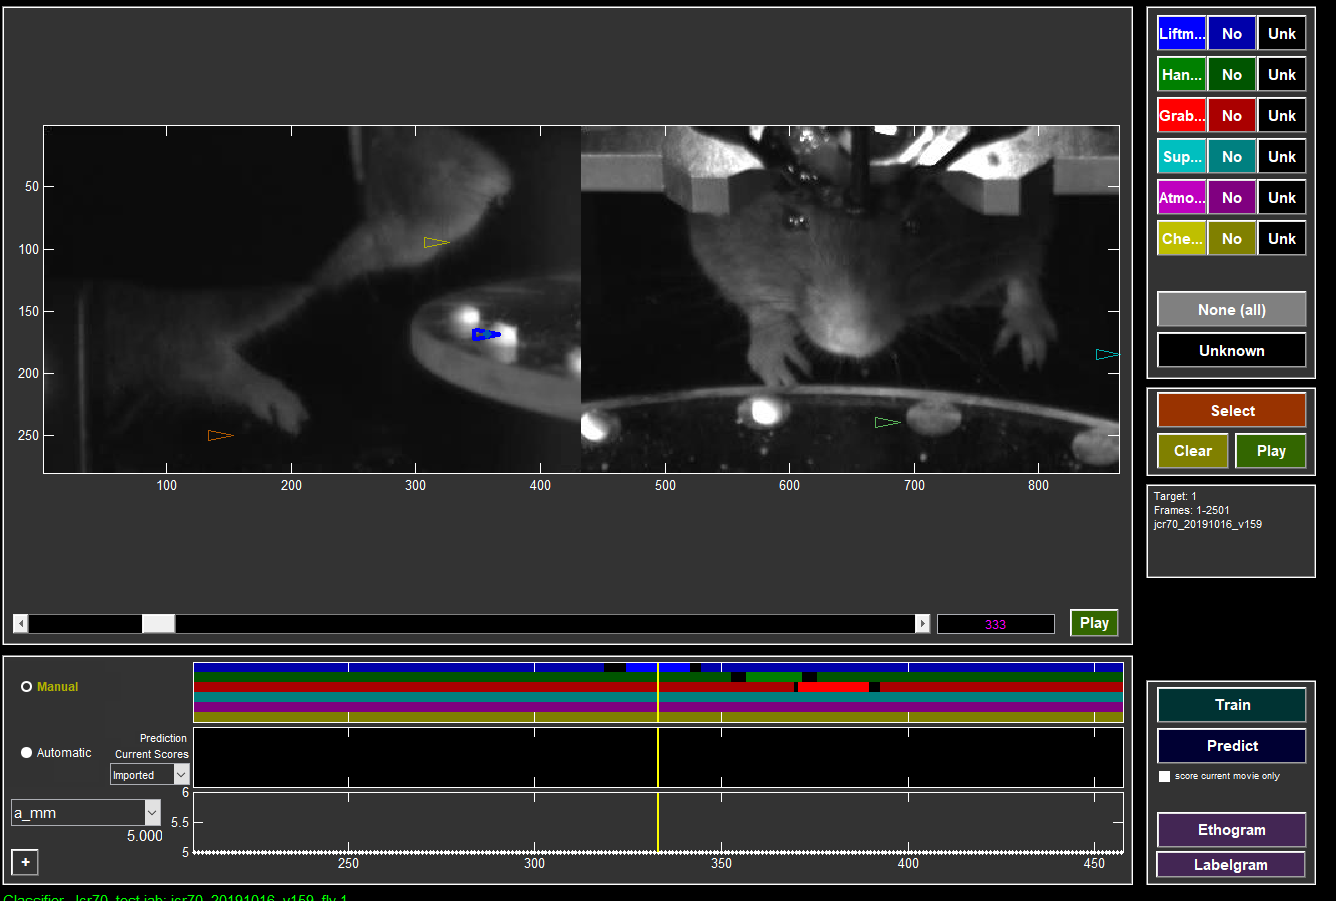

- Lift: Moment hand lifts off of table to about mid-reach or less

- Hand open: Moment hand beings to open/spread digits to max open frame (right before begins to close)

- Grab: max hand open to close formation

- Supinate: this part is longer, the whole twisting formation from hand facing pellet to hand facing mouse

- At mouth:hand at mouth, particularly the action of pushing the pellet into the mouth

- Chewing: When you see white of pellet in the mouths

**Train**

Select Large Train button in Gui to train the algorithm over your labels.

**Predict**

Select Large Prediction button in GUI to see how well the algorithm does in a couple of videos. Retrain more videos if performance is not good.

**Ethogram**

Open a second instance of MATLAB 2014 to run post processing script.

 addpath(genpath(JAABAST));
 SESSION = [MOVIES 'JAABA_Combo\'];
 SESSION = {SESSION};
 [red,jabfiles,T0,T1] = ethogram_plot(SESSION,[],1500,'automarks',true,'exptags','readfromjabs');

Select Classifier of Choice  on left side of GUI > Click Add Button > Done

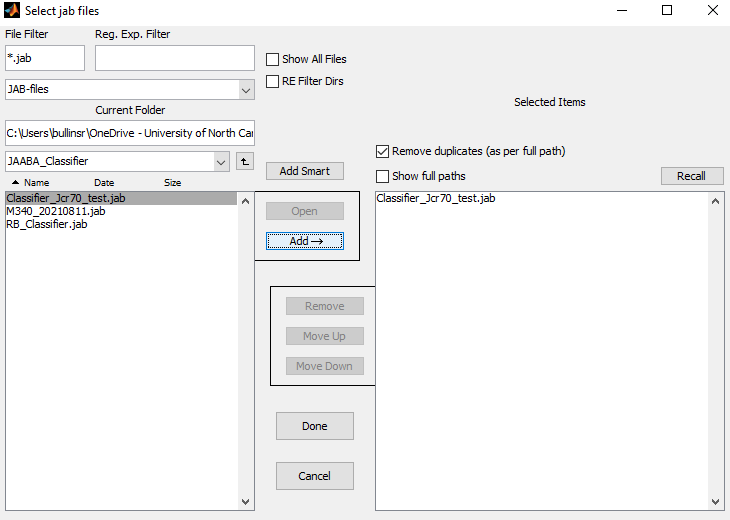

Ethogram plot will appear. 

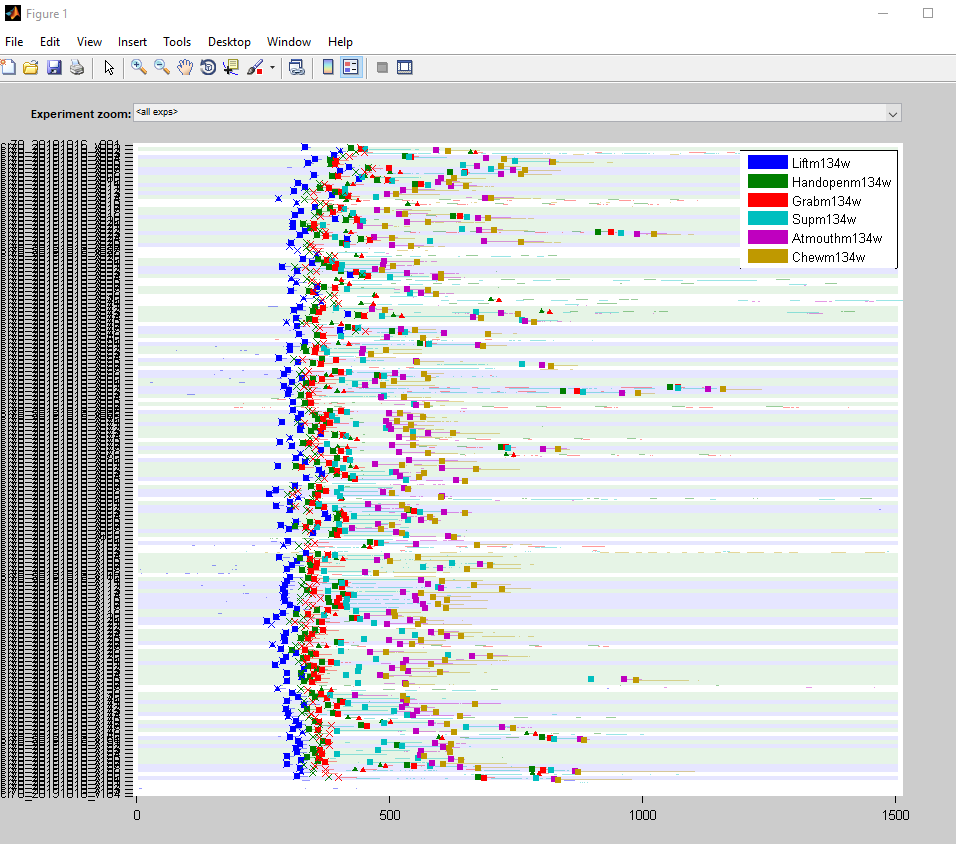

Now compare ethogram plot to manually labeled scored videos. Manual scores are scored as follows and should be stored in an excel sheet titled 'SUB_EXPERSESSION_ReachResults.xlsx'. Excel sheet should be saved in the directory with the movies. Ethogram corresponding colors are also shown below in ().

g: Grooming                               (white)

-1: Reach and no success         (white)

0: Does not attempt reach         (white)

1: Single reach and success     (green)

2: Double reach and success    (purple)

How well does the ethogram compare to your manually scored excel sheet? Repeat training until well matched.

**Export JAABA Scores**

Once matched well, run ethogram plot code again. Then Select Export Workspace.

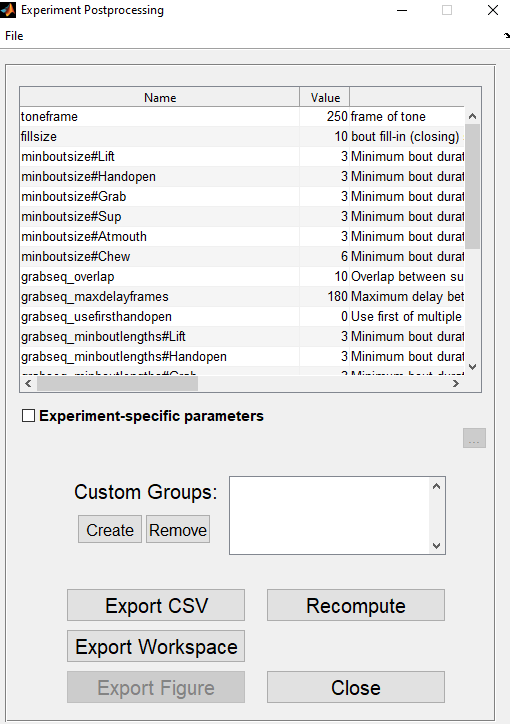

**Save**

Save to Data_Analyzed > JAABA_Output > SUB_EXPERSESSION_JAABA_Output.mat

 save([BASEPATH 'Data_Analyzed\JAABA_Output\' SUB '_' EXPER_SESSION '_JAABA_Output.mat'],'data','stats');